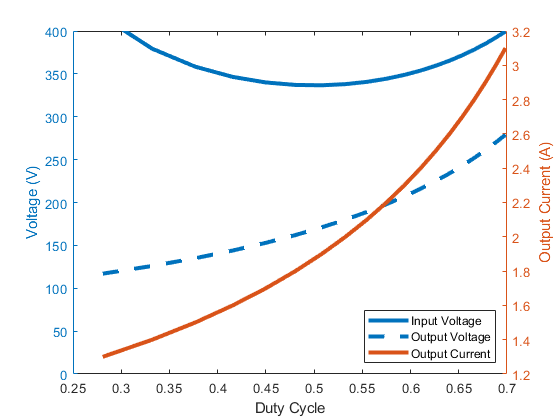

clear all
Rload = 90; %ohms
fsw = 450e3;
Iout = 1:0.1:20; %A
DeltaI = 27.5;
IndMaxPeak = (Iout + DeltaI)/2;
IndMinPeak = (Iout - DeltaI)/2;
L = 6.8e-6;
D = 1- L*DeltaI*fsw./(Rload*Iout);
Vout = Iout*Rload;
Vin = Vout./D;
[~,ix2] = min(abs(Vin-400));
[~,ix1] = min(abs(Vin(1:ix2-10)-400));
%  ix1 = ix2;
%  ix2 = 191;


figure
yyaxis left
hold on
plot(D(ix1:ix2),Vin(ix1:ix2), 'LineWidth', 3);
plot(D(ix1:ix2),Vout(ix1:ix2), 'LineWidth', 3);
hold off
ylim([0 400])
ylabel('Voltage (V)')
yyaxis right
plot(D(ix1:ix2),Iout(ix1:ix2),'LineWidth', 3);
xlabel('Duty Cycle')
ylabel('Output Current (A)')
legend('Input Voltage','Output Voltage','Output Current','Location','southeast')

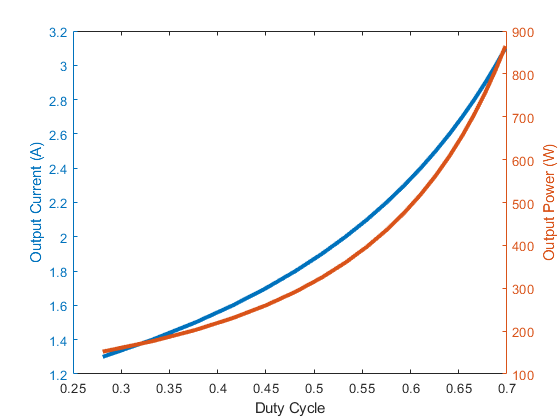


Pout = Rload*Iout.^2;

figure
yyaxis left
plot(D(ix1:ix2),Iout(ix1:ix2), 'LineWidth', 3);
ylabel('Output Current (A)')
yyaxis right
plot(D(ix1:ix2),Pout(ix1:ix2),'LineWidth', 3);
xlabel('Duty Cycle')
ylabel('Output Power (W)')

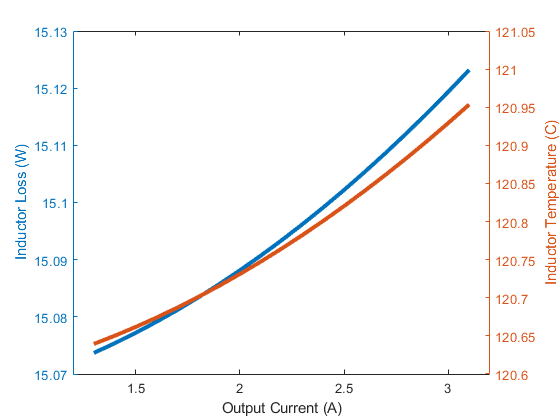


Rdc = 50e-3;
Rac = 75e-3;
Iacrms = (DeltaI)/2/sqrt(3);
Idc = Iout/2/2;
Pwind = Idc.^2*Rdc*2 + Iacrms^2*Rac*2;
Psp = 0.55*10^3; % kW/m^3
Ve = 10200; %mm^3
Pcore = Psp*1e3 * Ve/1e9;
Pind = Pwind + Pcore;

Pref = 1.5.^2*Rdc*2 + Iacrms^2*Rac*2 + Pcore;
deltaT = (122-25)/Pref*Pind;
T = 25 + deltaT;

figure
yyaxis left
plot(Iout(ix1:ix2),Pind(ix1:ix2), 'LineWidth', 3);
ylabel('Inductor Loss (W)')
yyaxis right
plot(Iout(ix1:ix2),T(ix1:ix2),'LineWidth', 3);
xlabel('Output Current (A)')
ylabel('Inductor Temperature (C)')